# Classifying ECG Signals (Part 1 - CNNs)

We will use deep learning to classify the same ECG dataset using two techniques:

- CNN - Convolutional Neural Network

- LSTM - Long Short-Term Memory Network

## Are You in the Correct Directory?

Your current folder browser should look like this:

% Run this to check
if isfolder('6-AdditionalFiles') && isfolder('6-Wavelets')
    disp('You are in the correct directory. Please continue.')
    addpath(genpath(pwd))
else  
    disp('Please navigate to the proper Directory')
end

## Access and View the Dataset

The networks we train will detect whether an echocardiogram (ECG) signal comes from a heart with: 

- *Normal Sinus Rhythm (NSR)*

- * Arrythmia (ARR) *

- *Congestive Heart Failure (CHF)*

The data are 162 sample signals, sampled at a frequency (Fs) of 128Hz.

load('ECGData.mat')

subplot(3,1,1); plot(Normal_Sample); title('NSR')
subplot(3,1,2); plot(Arrythmia_Sample); title('ARR')
subplot(3,1,3); plot(HeartFailure_Sample); title('CHF')

## Preprocess Data for CNN

To train a CNN, we first have to convert our signals into images that exhibit unique characteristics for each class. One approach that works for this data set is to convert the data to the time-frequncy spectrum using [continuous wavelet transform](https://www.mathworks.com/help/wavelet/gs/continuous-wavelet-transform-and-scale-based-analysis.html).

% Use the drop down to change the condition
sampleCondition = HeartFailure_Sample;
cwt(sampleCondition)

Open the [`PrepareSignalData.mlx`](matlab:edit('PrepareSignalData.mlx');) file.  This script applies the continuous wavelet transform to all the siganls and saves the images in 'data' folder. This step has already been done, so **you do not run the script**. 

% edit PrepareSignalData.mlx

## View Processed Data

filePath = '6-Wavelets';
imds = imageDatastore(filePath, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

heartRhythm = "CHF";
idx = find(string(imds.Labels) == heartRhythm);

for i = 1:4
    selectIdx = idx(randi(numel(idx)));
    im = imread(imds.Files{selectIdx});
    subplot(2,2,i)
    imshow(im)
    title(string(imds.Labels(selectIdx)));
end

## Split Data into Training and Test Images

[trainingImages, testImages] = splitEachLabel(imds, 0.8, 'randomize');

Resize the images to fit the network we will build. Our network will have an input size requirement of 227x227 pixels.

inputSize = [227 227];
trainingImagesR = augmentedImageDatastore(inputSize, trainingImages);
testImagesR = augmentedImageDatastore(inputSize, testImages);

## Build CNN with Transfer Learning

deepNetworkDesigner

## **Step 1: Import SqueezeNet**

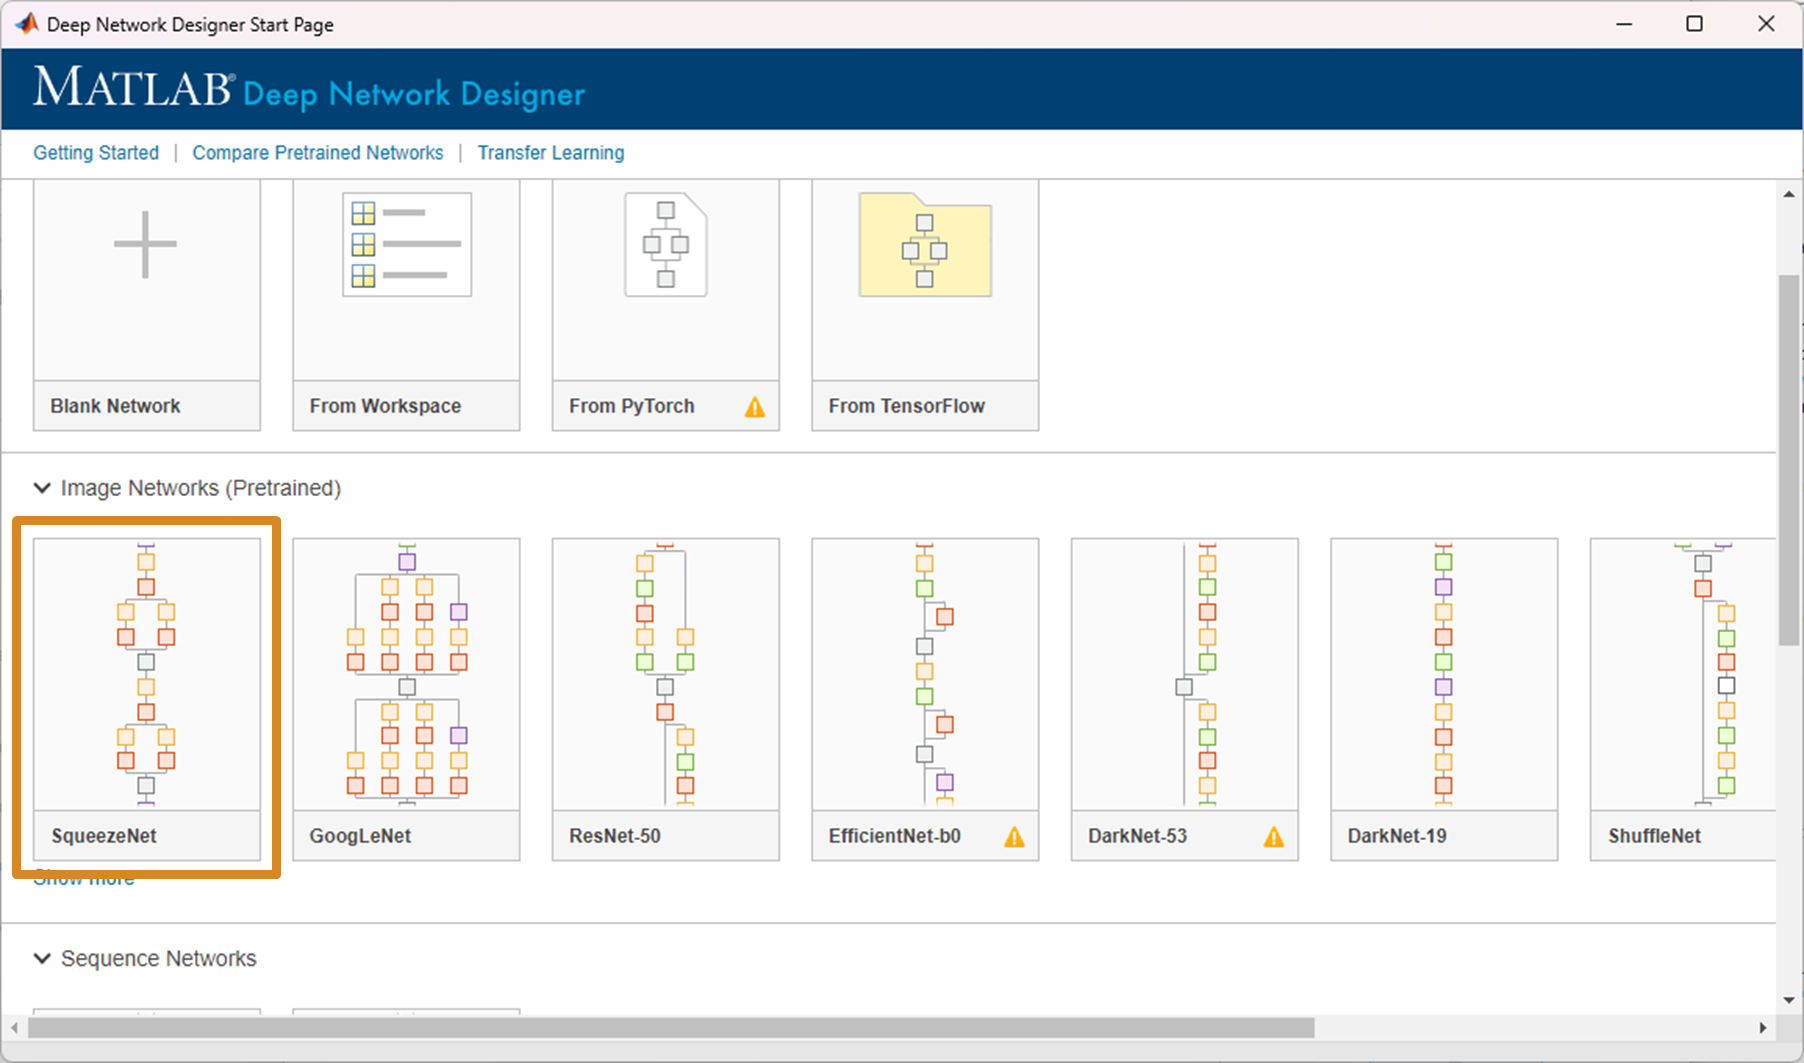

## **Step 2: Replace last learnable layer with new layer**

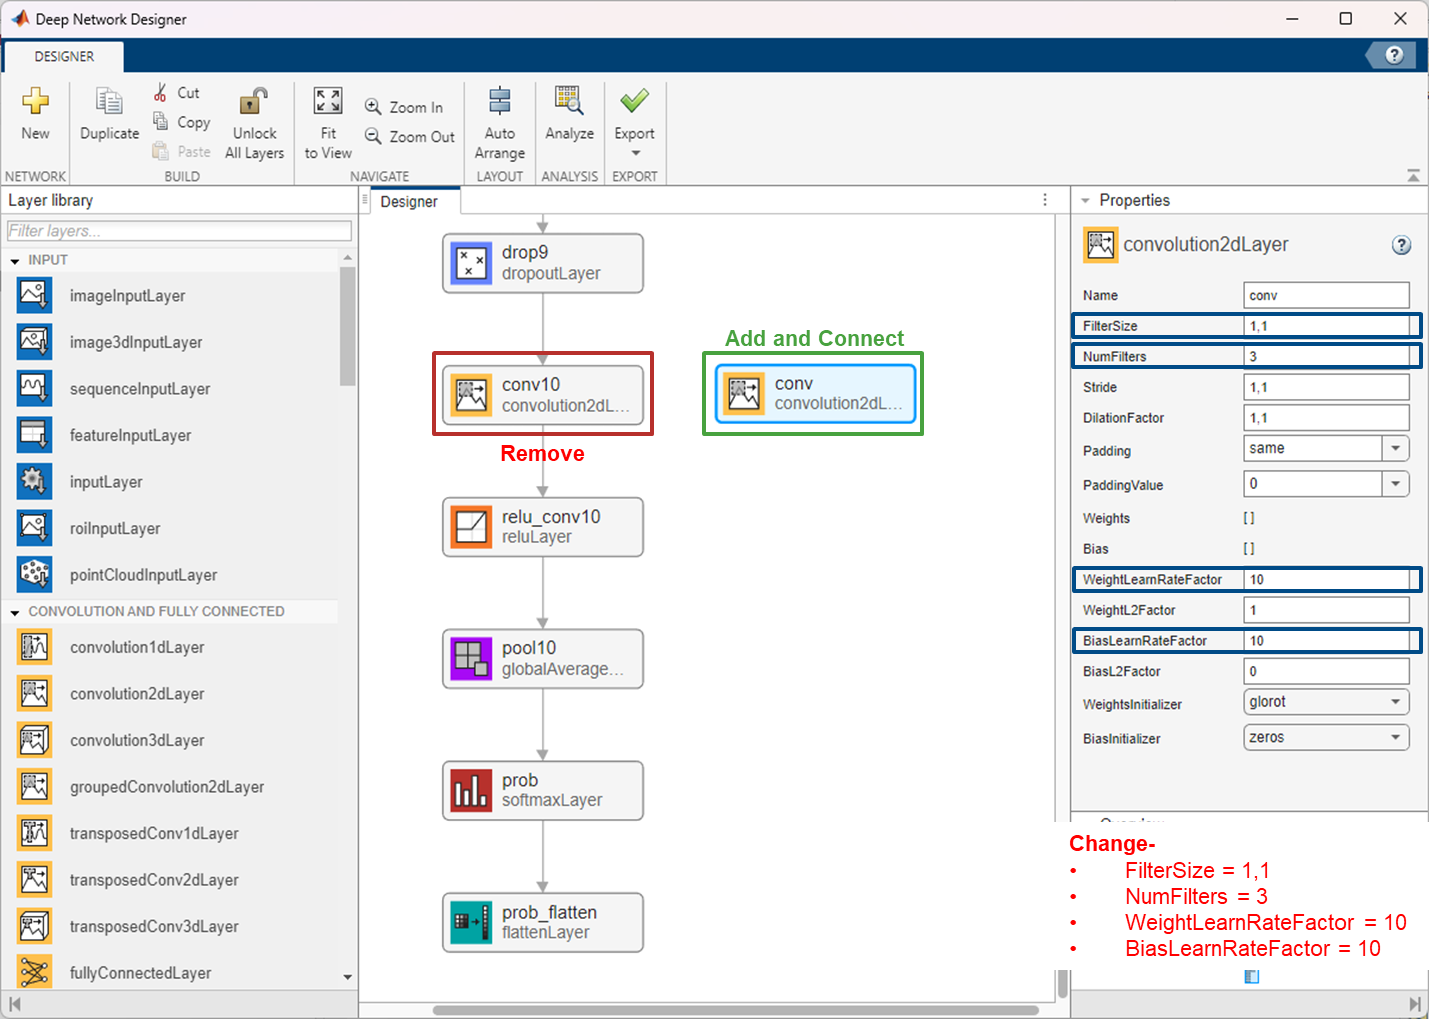

## **Step 3: Export network to workspace**

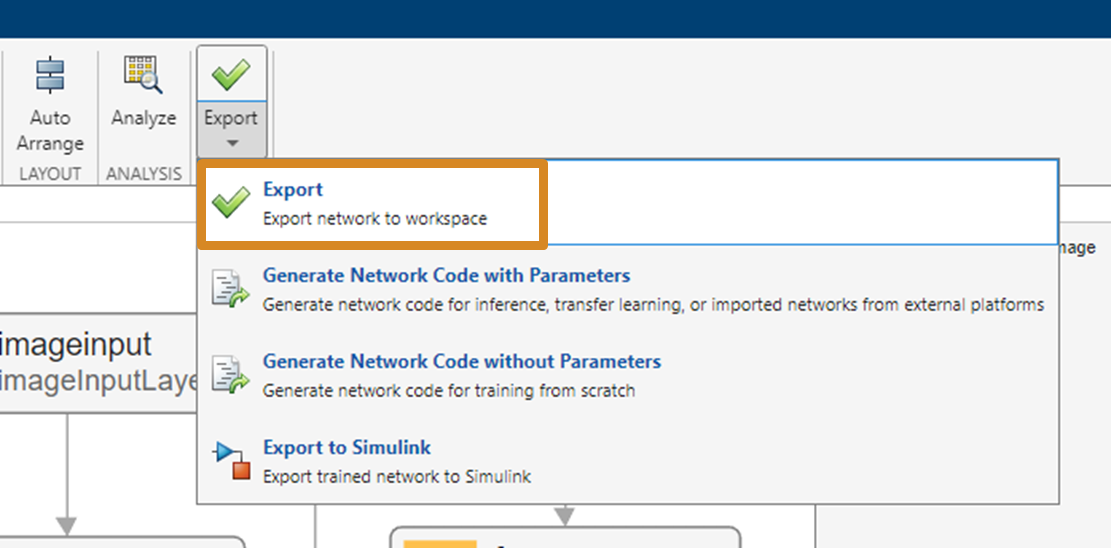

## **Step 4: **Set Hyperparameters and Train Network

Use the following training options and save them to variable "options"

- InitialLearnRate = 0.0001

- MaxEpochs = 12

- MiniBatchSize = 10

- Plots = "training-progress"

- Metrics = "accuracy"

- Verbose = false

Check [Options for training deep learning neural network ](https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html)for help

% InitialLearnRate = 
% MaxEpochs = 
% MiniBatchSize = 
% Plots = 
% Metrics = 
% Verbose = 

% ADD CODE HERE

options = trainingOptions("sgdm", ...
    'InitialLearnRate', InitialLearnRate, ...
    'MaxEpochs', MaxEpochs, ...
    'MiniBatchSize', MiniBatchSize, ...
    'Plots', Plots , ...
    'Metrics', Metrics , ...
    'Verbose', Verbose );



% Make sure the name of network is same as the name of the network exported
% from Deep Network Designer
ECGNet = trainnet(trainingImagesR, net_1, "crossentropy",options); 

## Test the Network

scores = minibatchpredict(ECGNet, testImagesR);

classNames = categories(trainingImages.Labels);
labels = scores2label(scores, classNames);

accuracy = sum(labels == testImages.Labels)*100 / numel(labels)

cm = confusionchart(labels, testImages.Labels);
figure
cm.RowSummary = 'row-normalized';
cm.Title = ['ECG Classification Accuracy = ' num2str(accuracy) '%'];

## Classify Signals using LSTM

Try out part 2 of the exercise.

edit Work_ECG_LSTM.mlx

*Copyright 2024 The MathWorks, Inc.*